clear all 
clc

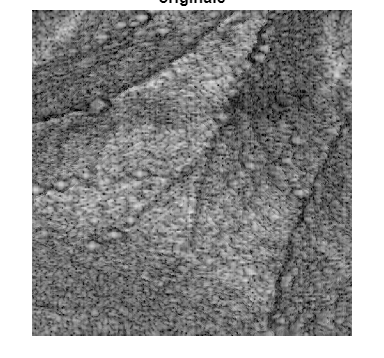

% im = fullfile("imageGeneratedFrom3D/Luongo_1_rimozioneRes_000/immagine_1_0.0924.jpg");
% im = fullfile("imageGeneratedFrom3D/Scavone_rimozioneRes_004/immagine_1_0.0924.jpg");
% im = fullfile("imageGeneratedFrom3D/Scavone_sogliaAuto_004/immagine_1_0.0924.jpg");
im = fullfile("imageGeneratedFrom3D/Luongo_1_sogliaAuto_000/immagine_1_0.0924.jpg");

I = imread(im);
originale = I;
imshow(I);title('originale');figure;

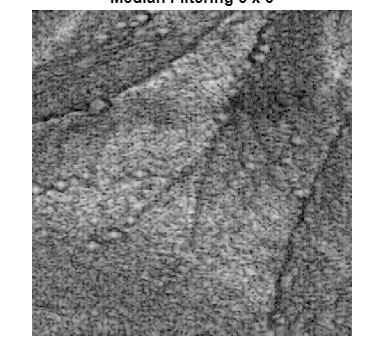

% Step 1: Noise Reduction and Enhancement
% You can apply filters to reduce noise and enhance features.
% Example: Using Median Filtering
filtered_image = medfilt2(I, [3, 3]);
imshow(filtered_image);title('Median Filtering 3 x 3');figure;

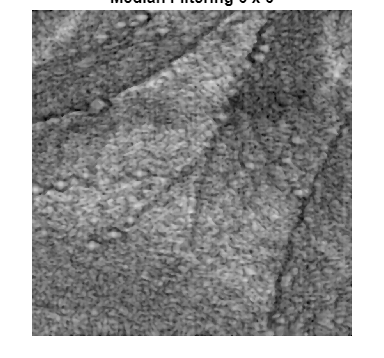


filtered_image1 = medfilt2(I, [6, 6]);
imshow(filtered_image1);title('Median Filtering 6 x 6');figure;

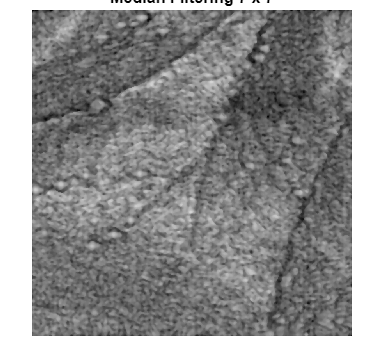


filtered_image4 = medfilt2(I, [7, 7]);
imshow(filtered_image4);title('Median Filtering 7 x 7');figure;

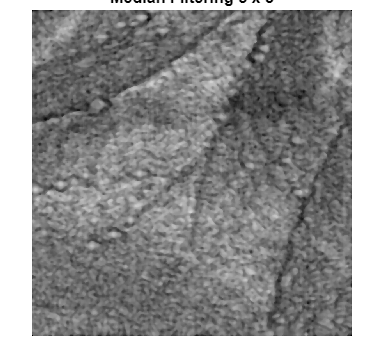


filtered_image5 = medfilt2(I, [8, 8]);
imshow(filtered_image5);title('Median Filtering 8 x 8');figure;

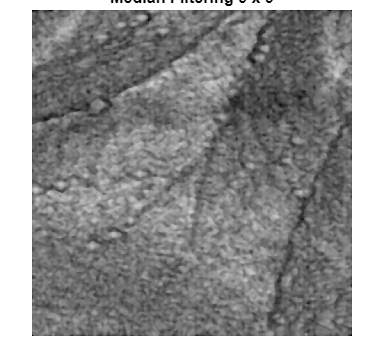


filtered_image2 = medfilt2(I, [9, 9]);
imshow(filtered_image2);title('Median Filtering 9 x 9');figure;

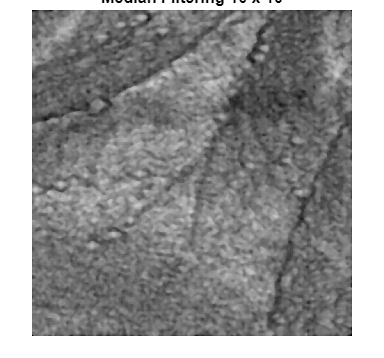


filtered_image3 = medfilt2(I, [10, 10]);
imshow(filtered_image3);title('Median Filtering 10 x 10');figure;

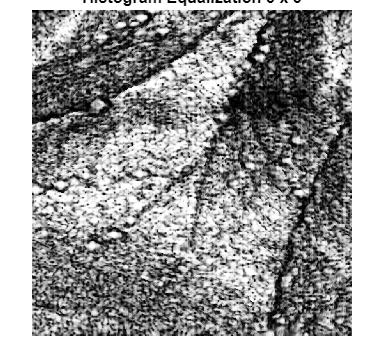

% Step 2: Image Enhancement (Optional)
% If needed, you can enhance the image using techniques like histogram equalization or adaptive histogram equalization.
% Example: Using Histogram Equalization
enhanced_image = histeq(filtered_image);
imshow(enhanced_image);title('Histogram Equalization 3 x 3');figure;

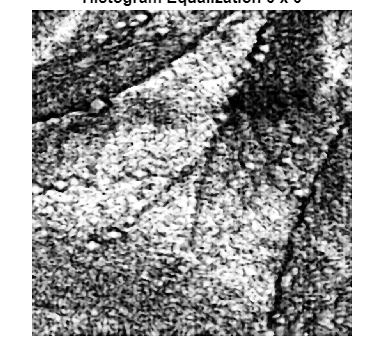


enhanced_image1 = histeq(filtered_image1);
imshow(enhanced_image1);title('Histogram Equalization 6 x 6');figure;

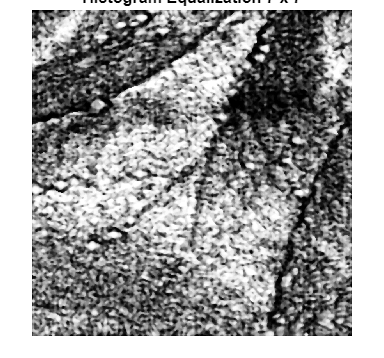


enhanced_image4 = histeq(filtered_image4);
imshow(enhanced_image4);title('Histogram Equalization 7 x 7');figure;

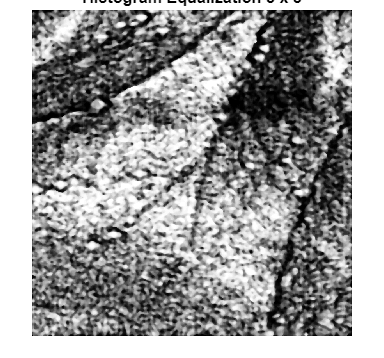


enhanced_image5 = histeq(filtered_image5);
imshow(enhanced_image5);title('Histogram Equalization 8 x 8');figure;

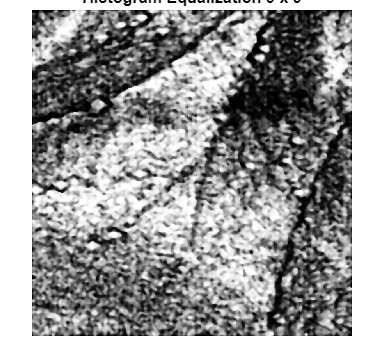


enhanced_image2 = histeq(filtered_image2);
imshow(enhanced_image2);title('Histogram Equalization 9 x 9');figure;

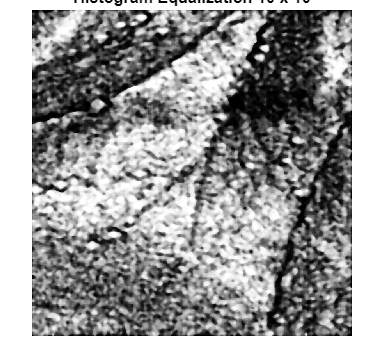


enhanced_image3 = histeq(filtered_image3);
imshow(enhanced_image3);title('Histogram Equalization 10 x 10');figure;

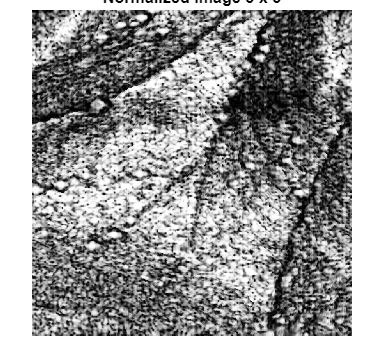

% Step 3: Normalization (Optional)
% If your image data is not already in the desired range, you can normalize it to [0, 1].
% Example: Min-Max Normalization
normalized_image = double(enhanced_image) / 255.0;
imshow(normalized_image);title('Normalized Image 3 x 3');figure;

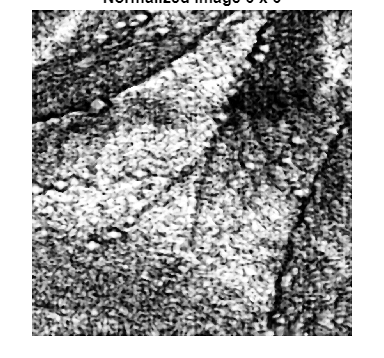


normalized_image1 = double(enhanced_image1) / 255.0;
imshow(normalized_image1);title('Normalized Image 6 x 6');figure;

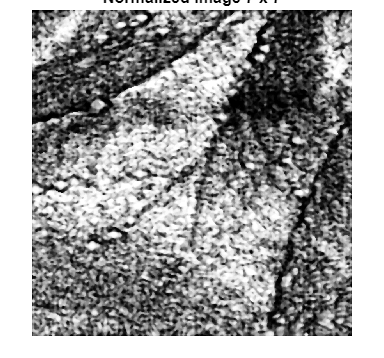


normalized_image4 = double(enhanced_image4) / 255.0;
imshow(normalized_image4);title('Normalized Image 7 x 7');figure;

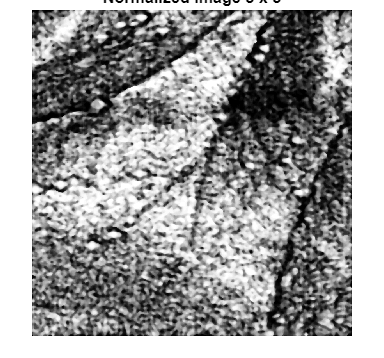


normalized_image5 = double(enhanced_image5) / 255.0;
imshow(normalized_image5);title('Normalized Image 8 x 8');figure;

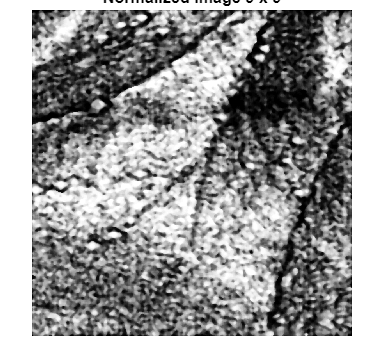


normalized_image2 = double(enhanced_image2) / 255.0;
imshow(normalized_image2);title('Normalized Image 9 x 9');figure;

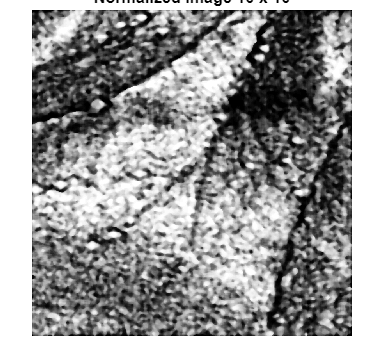


normalized_image3 = double(enhanced_image3) / 255.0;
imshow(normalized_image3);title('Normalized Image 10 x 10');figure;

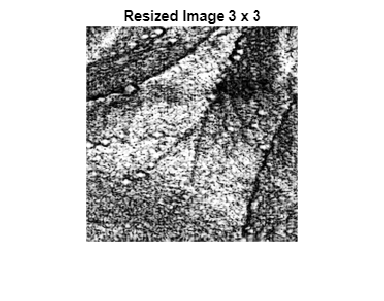

%RESIZE DELL'IMMAGINE
im=imresize(normalized_image, 0.25, 'bicubic'); % imposto la grandezza dell'immagine mantenendo le proporzioni
imshow(im);title('Resized Image 3 x 3');figure;

[dim1, dim2] = size(im);
fprintf('Dimensione immagine: %.0f x %.0f', dim1, dim2);

Dimensione immagine: 209 x 205

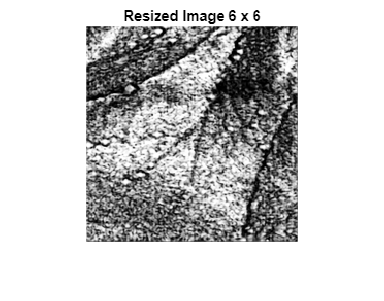


im1=imresize(normalized_image1, 0.25, 'bicubic'); % imposto la grandezza dell'immagine mantenendo le proporzioni
imshow(im1);title('Resized Image 6 x 6');figure;

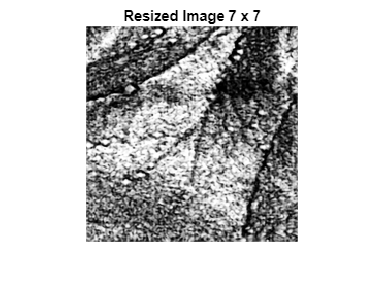


im4=imresize(normalized_image4, 0.25, 'bicubic'); % imposto la grandezza dell'immagine mantenendo le proporzioni
imshow(im4);title('Resized Image 7 x 7');figure;

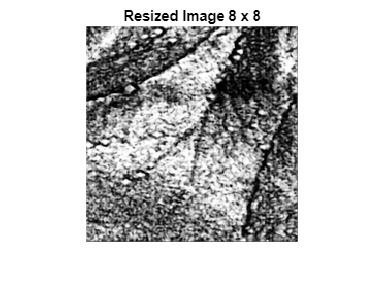


im5=imresize(normalized_image5, 0.25, 'bicubic'); % imposto la grandezza dell'immagine mantenendo le proporzioni
imshow(im5);title('Resized Image 8 x 8');figure;

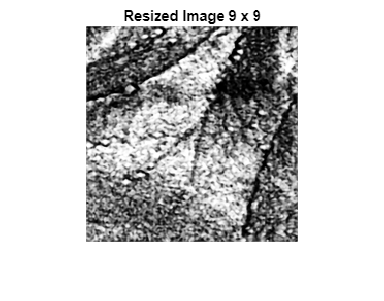


im2=imresize(normalized_image2, 0.25, 'bicubic'); % imposto la grandezza dell'immagine mantenendo le proporzioni
imshow(im2);title('Resized Image 9 x 9');figure;

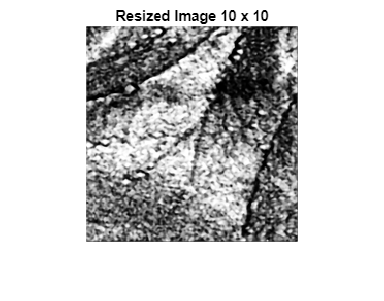


im3=imresize(normalized_image3, 0.25, 'bicubic'); % imposto la grandezza dell'immagine mantenendo le proporzioni
imshow(im3);title('Resized Image 10 x 10');figure;

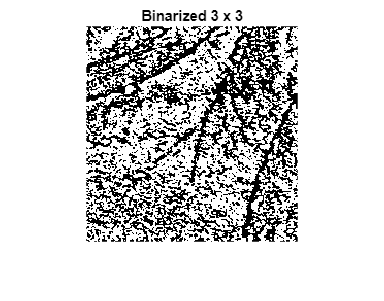

%BINARIZZAZIONE
A = im;
BW = imbinarize(A, "adaptive", "ForegroundPolarity","dark");
imshow(BW); title(['Binarized 3 x 3']); figure;

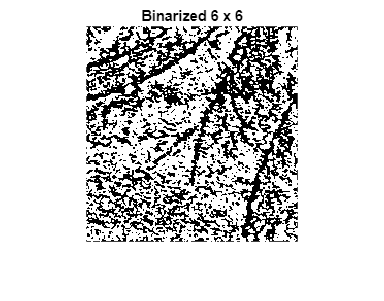


A1 = im1;
BW1 = imbinarize(A1, "adaptive", "ForegroundPolarity","dark");
imshow(BW1); title(['Binarized 6 x 6']); figure;

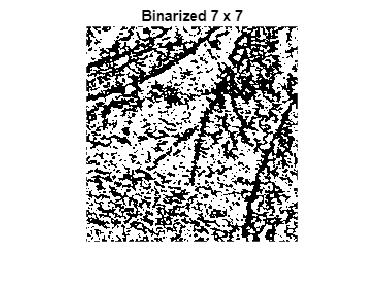


A4 = im4;
BW4 = imbinarize(A4, "adaptive", "ForegroundPolarity","dark");
imshow(BW4); title(['Binarized 7 x 7']); figure;

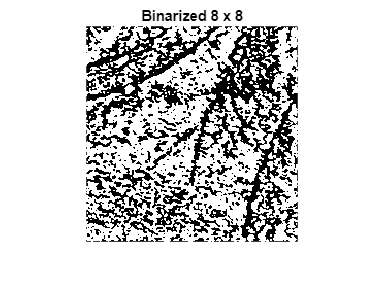


A5 = im5;
BW5 = imbinarize(A5, "adaptive", "ForegroundPolarity","dark");
imshow(BW5); title(['Binarized 8 x 8']); figure;

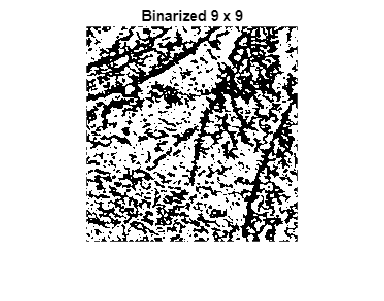


A2 = im2;
BW2 = imbinarize(A2, "adaptive", "ForegroundPolarity","dark");
imshow(BW2); title(['Binarized 9 x 9']); figure;

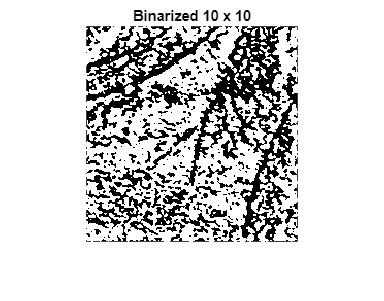


A3 = im3;
BW3 = imbinarize(A3, "adaptive", "ForegroundPolarity","dark");
imshow(BW3); title(['Binarized 10 x 10']); figure;

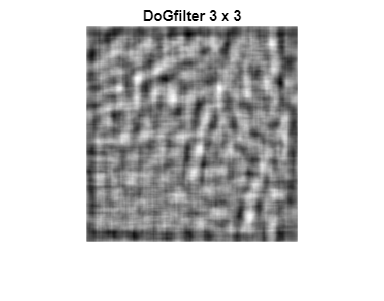

%APPLICAZIONE FILTRO DoG
gaussian1 = fspecial('gaussian',21,10); 
gaussian2 = fspecial('gaussian',21,13);
gaussian = gaussian2 - gaussian1;

dogFilterImage = conv2(double(BW), gaussian, 'same');
imshow(dogFilterImage,[]);title('DoGfilter 3 x 3');figure;

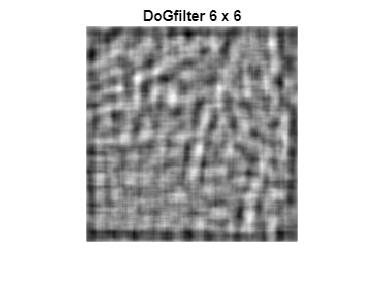



dogFilterImage1 = conv2(double(BW1), gaussian, 'same');
imshow(dogFilterImage1,[]);title('DoGfilter 6 x 6');figure;

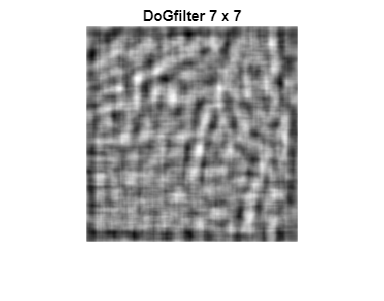


dogFilterImage4 = conv2(double(BW4), gaussian, 'same');
imshow(dogFilterImage4,[]);title('DoGfilter 7 x 7');figure;

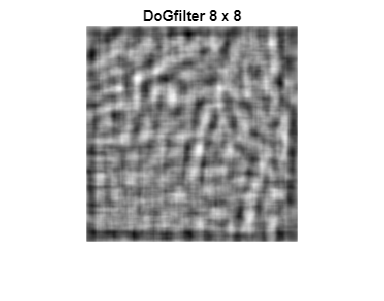


dogFilterImage5 = conv2(double(BW5), gaussian, 'same');
imshow(dogFilterImage5,[]);title('DoGfilter 8 x 8');figure;

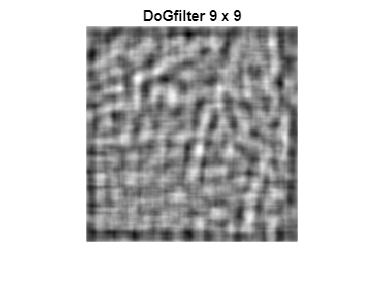


dogFilterImage2 = conv2(double(BW2), gaussian, 'same');
imshow(dogFilterImage2,[]);title('DoGfilter 9 x 9');figure;

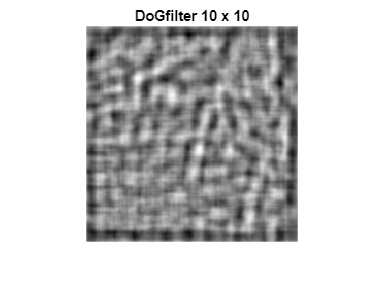


dogFilterImage3 = conv2(double(BW3), gaussian, 'same');
imshow(dogFilterImage3,[]);title('DoGfilter 10 x 10');figure;

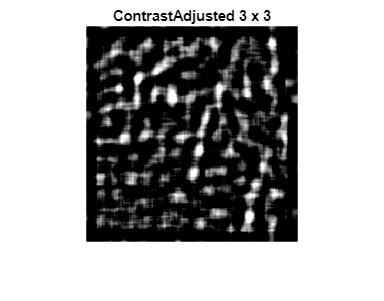

%AUMENTO CONTRASTO
contrastAdjusted = imadjust(dogFilterImage);
imshow(contrastAdjusted); title('ContrastAdjusted 3 x 3'); figure;

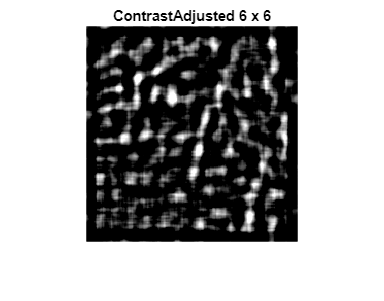


contrastAdjusted1 = imadjust(dogFilterImage1);
imshow(contrastAdjusted1); title('ContrastAdjusted 6 x 6'); figure;

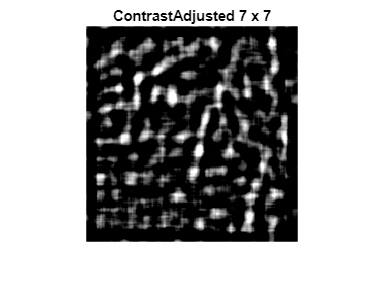


contrastAdjusted4 = imadjust(dogFilterImage4);
imshow(contrastAdjusted4); title('ContrastAdjusted 7 x 7'); figure;

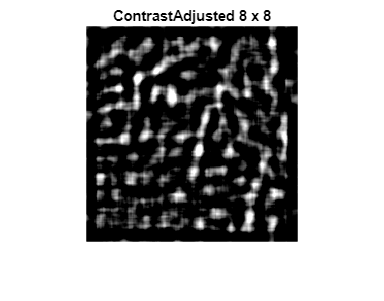


contrastAdjusted5 = imadjust(dogFilterImage5);
imshow(contrastAdjusted5); title('ContrastAdjusted 8 x 8'); figure;

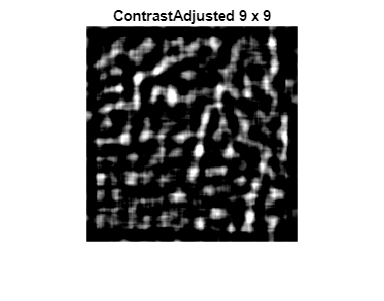


contrastAdjusted2 = imadjust(dogFilterImage2);
imshow(contrastAdjusted2); title('ContrastAdjusted 9 x 9'); figure;

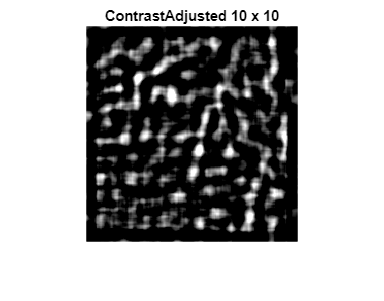


contrastAdjusted3 = imadjust(dogFilterImage3);
imshow(contrastAdjusted3); title('ContrastAdjusted 10 x 10'); figure;

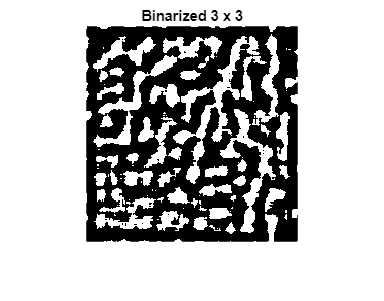

%BINARIZZAZIONE
A = contrastAdjusted;
BW = imbinarize(A, "adaptive", "ForegroundPolarity","dark");
imshow(BW); title(['Binarized 3 x 3']); figure;

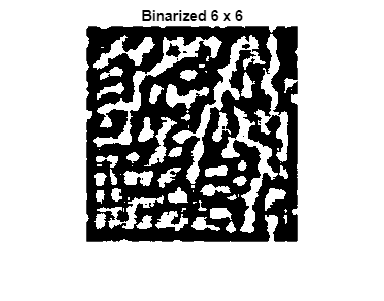


A1 = contrastAdjusted1;
BW1 = imbinarize(A1, "adaptive", "ForegroundPolarity","dark");
imshow(BW1); title(['Binarized 6 x 6']); figure;

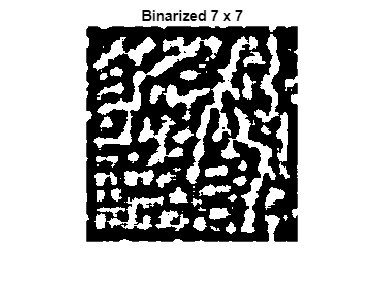


A4 = contrastAdjusted4;
BW4 = imbinarize(A4, "adaptive", "ForegroundPolarity","dark");
imshow(BW4); title(['Binarized 7 x 7']); figure;

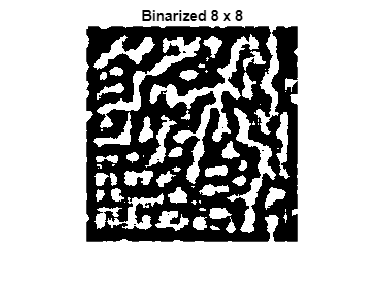


A5 = contrastAdjusted5;
BW5 = imbinarize(A5, "adaptive", "ForegroundPolarity","dark");
imshow(BW5); title(['Binarized 8 x 8']); figure;

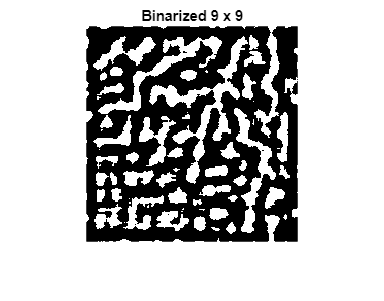


A2 = contrastAdjusted2;
BW2 = imbinarize(A2, "adaptive", "ForegroundPolarity","dark");
imshow(BW2); title(['Binarized 9 x 9']); figure;

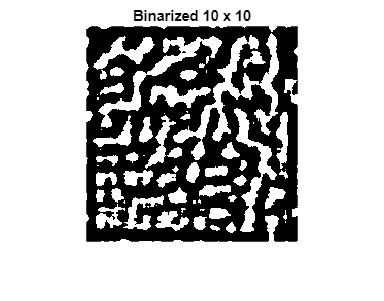


A3 = contrastAdjusted3;
BW3 = imbinarize(A3, "adaptive", "ForegroundPolarity","dark");
imshow(BW3); title(['Binarized 10 x 10']); figure;

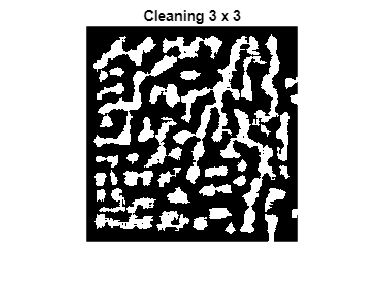

%CLEANING
CC= bwconncomp(BW);
S = regionprops(CC, 'Area');
L = labelmatrix(CC);  
BW_ = ismember(L, find([S.Area] >= 50));
imshow(BW_); title('Cleaning 3 x 3'); figure;

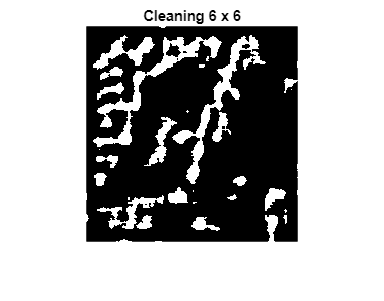


CC1= bwconncomp(BW1);
S1 = regionprops(CC1, 'Area');
L1 = labelmatrix(CC1);  
BW_1 = ismember(L1, find([S.Area] >= 50));
imshow(BW_1); title('Cleaning 6 x 6'); figure;

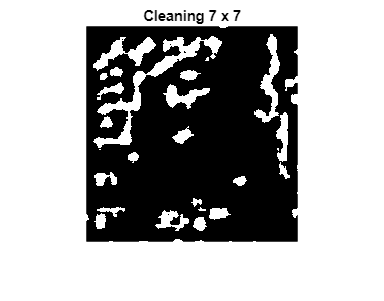


CC4= bwconncomp(BW4);
S4 = regionprops(CC4, 'Area');
L4 = labelmatrix(CC4);  
BW_4 = ismember(L4, find([S.Area] >= 50));
imshow(BW_4); title('Cleaning 7 x 7'); figure;

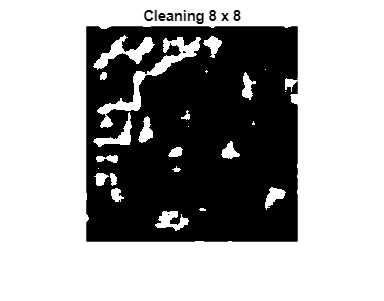


CC5= bwconncomp(BW5);
S5 = regionprops(CC5, 'Area');
L5 = labelmatrix(CC5);  
BW_5 = ismember(L5, find([S.Area] >= 50));
imshow(BW_5); title('Cleaning 8 x 8'); figure;

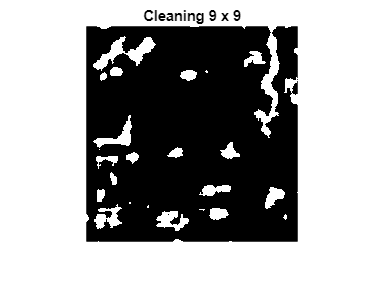


CC2= bwconncomp(BW2);
S2 = regionprops(CC2, 'Area');
L2 = labelmatrix(CC2);  
BW_2 = ismember(L2, find([S.Area] >= 50));
imshow(BW_2); title('Cleaning 9 x 9'); figure;

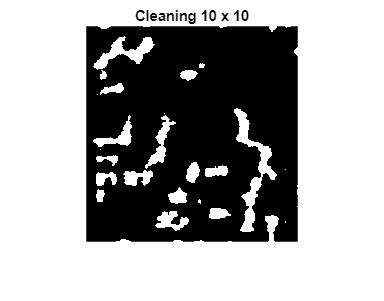


CC3= bwconncomp(BW3);
S1 = regionprops(CC3, 'Area');
L3 = labelmatrix(CC3);  
BW_3 = ismember(L3, find([S.Area] >= 50));
imshow(BW_3); title('Cleaning 10 x 10'); figure;

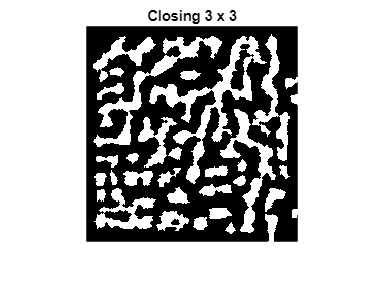

%CLOSING
se=strel('disk',1);
closing=imclose(BW_, se);
imshow(closing); title('Closing 3 x 3'); figure;

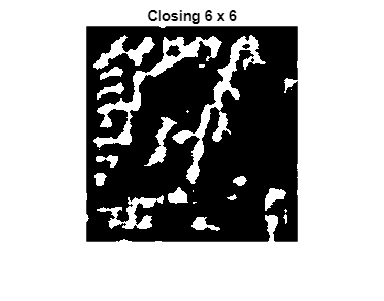


closing1=imclose(BW_1, se);
imshow(closing1); title('Closing 6 x 6'); figure;

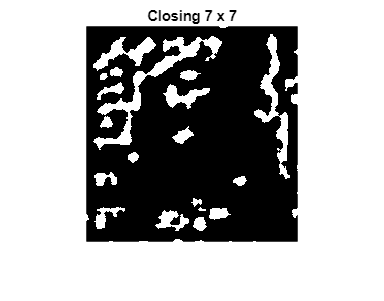


closing4=imclose(BW_4, se);
imshow(closing4); title('Closing 7 x 7'); figure;

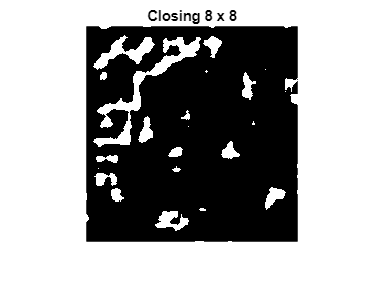


closing5=imclose(BW_5, se);
imshow(closing5); title('Closing 8 x 8'); figure;

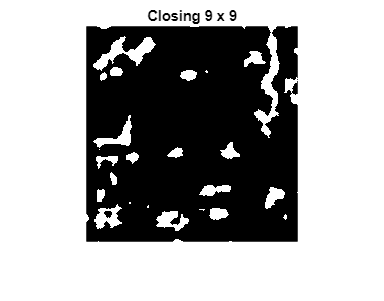


closing2=imclose(BW_2, se);
imshow(closing2); title('Closing 9 x 9'); figure;

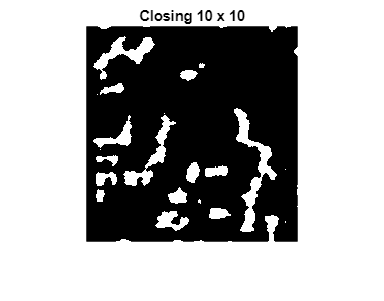


closing3=imclose(BW_3, se);
imshow(closing3); title('Closing 10 x 10'); figure;

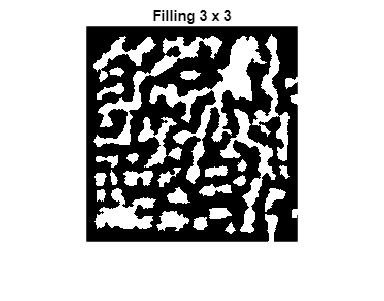

% FILLING
filling= imfill(closing, 'holes');
imshow(filling);title('Filling 3 x 3');figure;

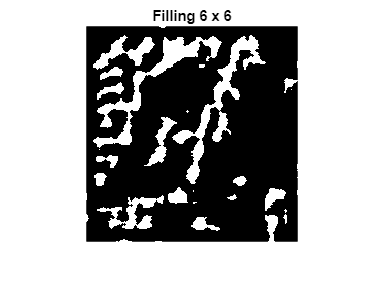


filling1= imfill(closing1, 'holes');
imshow(filling1);title('Filling 6 x 6');figure;

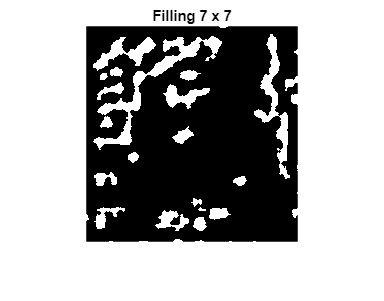


filling4= imfill(closing4, 'holes');
imshow(filling4);title('Filling 7 x 7');figure;

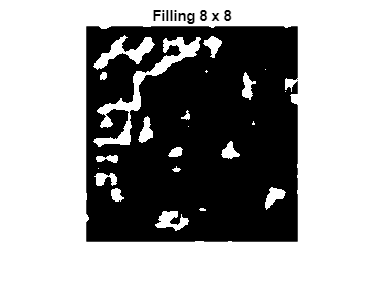


filling5= imfill(closing5, 'holes');
imshow(filling5);title('Filling 8 x 8');figure;

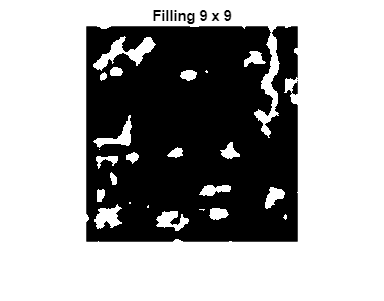


filling2= imfill(closing2, 'holes');
imshow(filling2);title('Filling 9 x 9');figure;

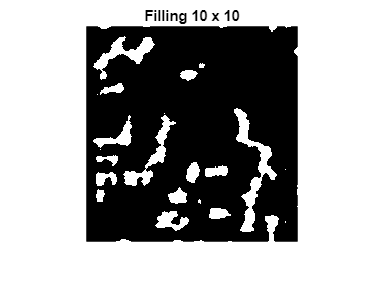


filling3= imfill(closing3, 'holes');
imshow(filling3);title('Filling 10 x 10');figure;

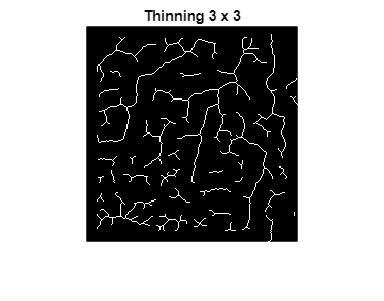

%THINNING
thinning= bwmorph(filling, 'thin', inf);
imshow(thinning);title('Thinning 3 x 3');figure;

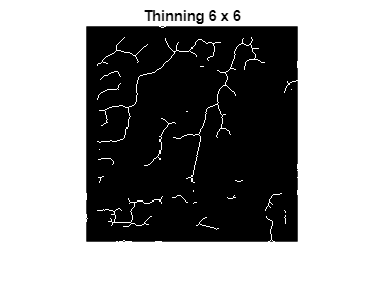


thinning1 = bwmorph(filling1, 'thin', inf);
imshow(thinning1);title('Thinning 6 x 6');figure;

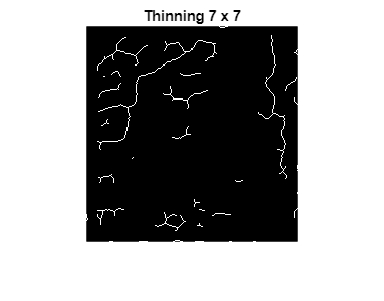


thinning4 = bwmorph(filling4, 'thin', inf);
imshow(thinning4);title('Thinning 7 x 7');figure;

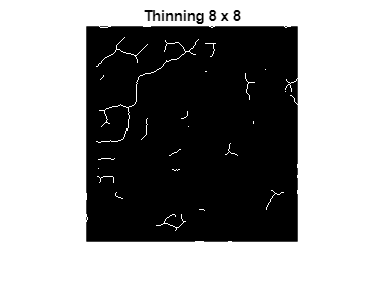


thinning5 = bwmorph(filling5, 'thin', inf);
imshow(thinning5);title('Thinning 8 x 8');figure;

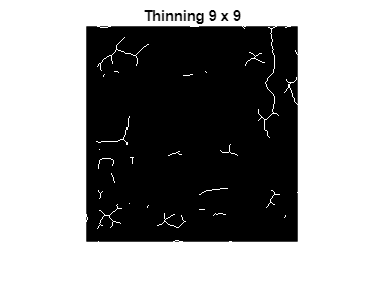


thinning2= bwmorph(filling2, 'thin', inf);
imshow(thinning2);title('Thinning 9 x 9');figure;

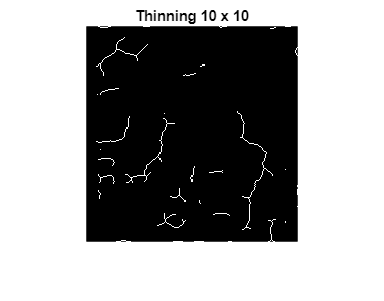


thinning3= bwmorph(filling3, 'thin', inf);
imshow(thinning3);title('Thinning 10 x 10');figure;

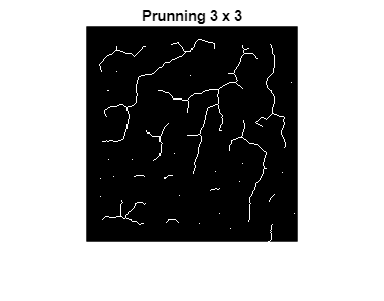

%PRUNNING
n_prun = 10;
prun = bwmorph(thinning, 'spur', n_prun);
imshow(prun);title('Prunning 3 x 3');figure;

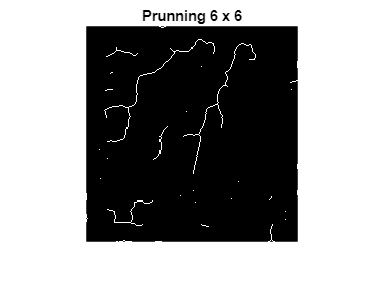


prun1 = bwmorph(thinning1, 'spur', n_prun);
imshow(prun1);title('Prunning 6 x 6');figure;

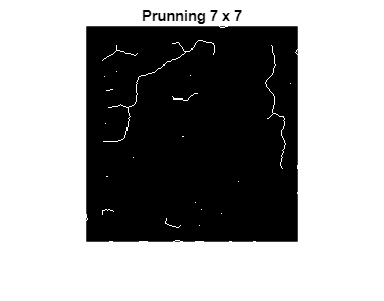


prun4 = bwmorph(thinning4, 'spur', n_prun);
imshow(prun4);title('Prunning 7 x 7');figure;

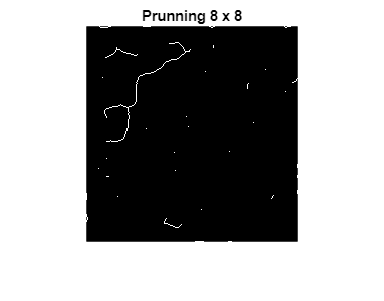


prun5 = bwmorph(thinning5, 'spur', n_prun);
imshow(prun5);title('Prunning 8 x 8');figure;

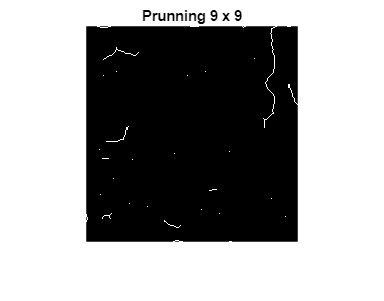


prun2 = bwmorph(thinning2, 'spur', n_prun);
imshow(prun2);title('Prunning 9 x 9');figure;

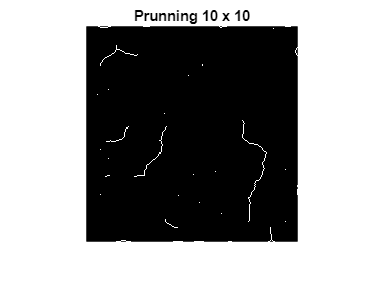


prun3 = bwmorph(thinning3, 'spur', n_prun);
imshow(prun3);title('Prunning 10 x 10');figure;

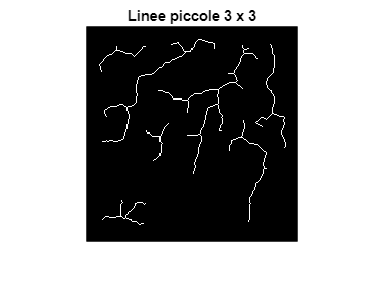

%CLEANING LINEE PICCOLE
n_cleaning = 50;
BWz = bwareaopen(prun, n_cleaning);
imshow(BWz);title('Linee piccole 3 x 3');figure;

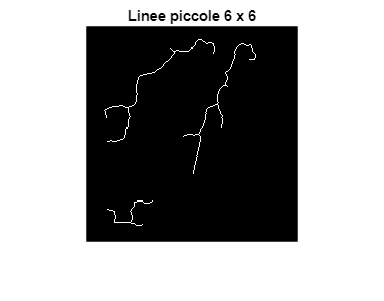


BWz1 = bwareaopen(prun1, n_cleaning);
imshow(BWz1);title('Linee piccole 6 x 6');figure;

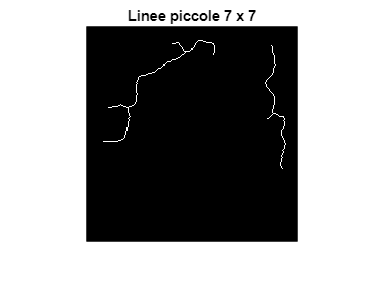


BWz4 = bwareaopen(prun4, n_cleaning);
imshow(BWz4);title('Linee piccole 7 x 7');figure;

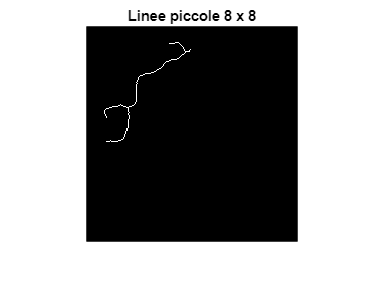


BWz5 = bwareaopen(prun5, n_cleaning);
imshow(BWz5);title('Linee piccole 8 x 8');figure;

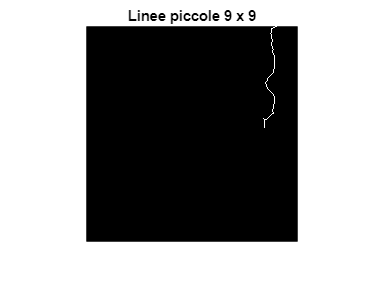


BWz2 = bwareaopen(prun2, n_cleaning);
imshow(BWz2);title('Linee piccole 9 x 9');figure;

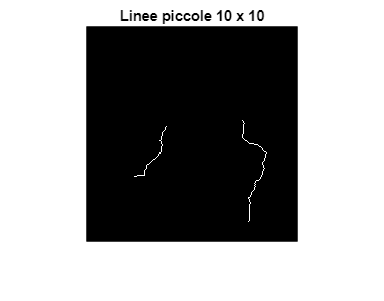


BWz3 = bwareaopen(prun3, n_cleaning);
imshow(BWz3);title('Linee piccole 10 x 10');figure;

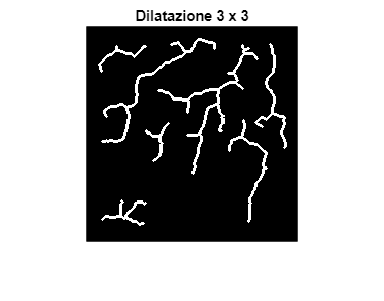

%DILATAZIONE
dilatation_mask= strel('disk', 1);
dilatedImage= imdilate(BWz, dilatation_mask);
imshow(dilatedImage); title('Dilatazione 3 x 3'); figure;

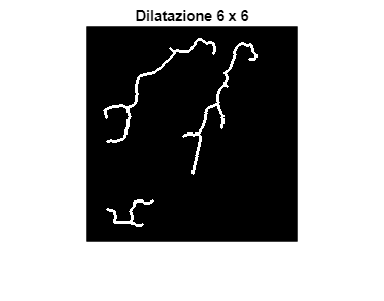


dilatedImage1= imdilate(BWz1, dilatation_mask);
imshow(dilatedImage1); title('Dilatazione 6 x 6'); figure;

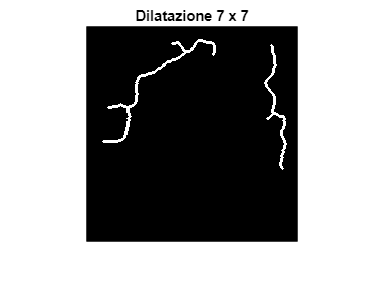


dilatedImage4= imdilate(BWz4, dilatation_mask);
imshow(dilatedImage4); title('Dilatazione 7 x 7'); figure;

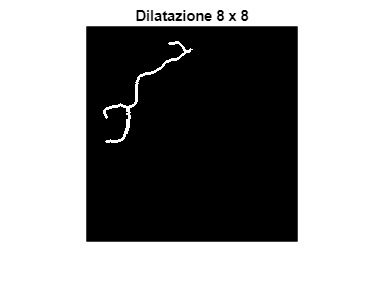


dilatedImage5= imdilate(BWz5, dilatation_mask);
imshow(dilatedImage5); title('Dilatazione 8 x 8'); figure;

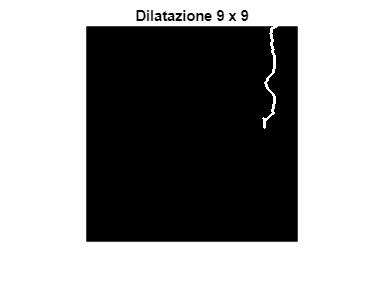


dilatedImage2= imdilate(BWz2, dilatation_mask);
imshow(dilatedImage2); title('Dilatazione 9 x 9'); figure;

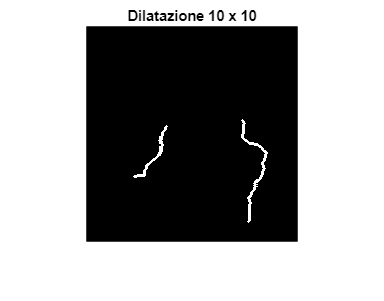


dilatedImage3= imdilate(BWz3, dilatation_mask);
imshow(dilatedImage3); title('Dilatazione 10 x 10'); figure;

originale = imresize(originale, 0.25, 'bicubic');
rgbImage = cat(3, originale, originale, originale);
rgbImage1 = cat(3, originale, originale, originale);
rgbImage2 = cat(3, originale, originale, originale);
rgbImage3 = cat(3, originale, originale, originale);
rgbImage4 = cat(3, originale, originale, originale);
rgbImage5 = cat(3, originale, originale, originale);

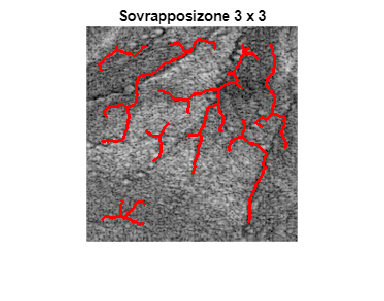

%SOVRAPPOSIZIONE
clear m n1

[m n1]= size(originale);% prima era size(I)
 for i=1 : m
    for j=1 : n1
        if  dilatedImage(i,j)==1
        %inputImage(i,j)=255;
        rgbImage(i,j,1)=255;
        rgbImage(i,j,2)=0;
        rgbImage(i,j,3)=0;
        end 
    end 
 end	 


imshow(rgbImage);title('Sovrapposizone 3 x 3'); figure;

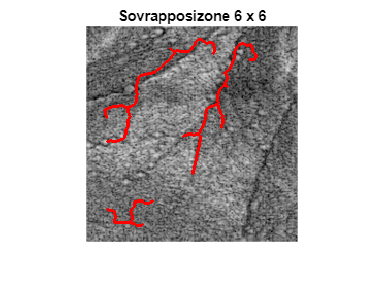


clear m n1
[m n1]= size(originale);% prima era size(I)
 for i=1 : m
    for j=1 : n1
        if  dilatedImage1(i,j)==1
        %inputImage(i,j)=255;
        rgbImage1(i,j,1)=255;
        rgbImage1(i,j,2)=0;
        rgbImage1(i,j,3)=0;
        end 
    end 
 end	 


imshow(rgbImage1);title('Sovrapposizone 6 x 6'); figure;

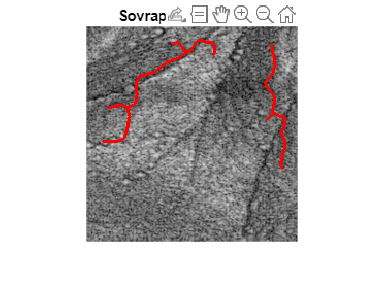


clear m n1
[m n1]= size(originale);% prima era size(I)
 for i=1 : m
    for j=1 : n1
        if  dilatedImage4(i,j)==1
        %inputImage(i,j)=255;
        rgbImage4(i,j,1)=255;
        rgbImage4(i,j,2)=0;
        rgbImage4(i,j,3)=0;
        end 
    end 
 end	 


imshow(rgbImage4);title('Sovrapposizone 7 x 7'); figure;

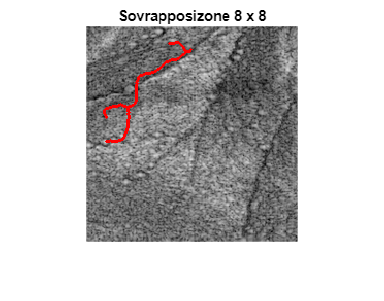


clear m n1
[m n1]= size(originale);% prima era size(I)
 for i=1 : m
    for j=1 : n1
        if  dilatedImage5(i,j)==1
        %inputImage(i,j)=255;
        rgbImage5(i,j,1)=255;
        rgbImage5(i,j,2)=0;
        rgbImage5(i,j,3)=0;
        end 
    end 
 end	 


imshow(rgbImage5);title('Sovrapposizone 8 x 8'); figure;

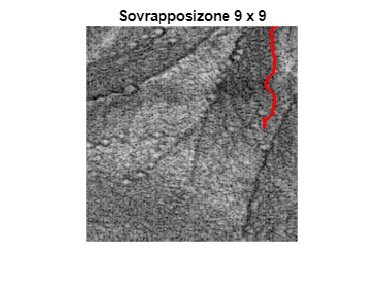



clear m n1
[m n1]= size(originale);% prima era size(I)
 for i=1 : m
    for j=1 : n1
        if  dilatedImage2(i,j)==1
        %inputImage(i,j)=255;
        rgbImage2(i,j,1)=255;
        rgbImage2(i,j,2)=0;
        rgbImage2(i,j,3)=0;
        end 
    end 
 end	 


imshow(rgbImage2);title('Sovrapposizone 9 x 9'); figure;

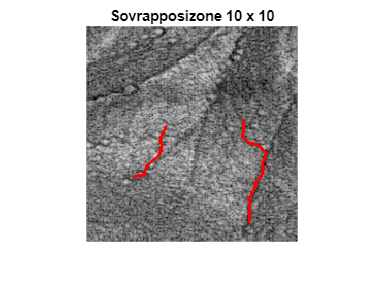


clear m n1
[m n1]= size(originale);% prima era size(I)
 for i=1 : m
    for j=1 : n1
        if  dilatedImage3(i,j)==1
        %inputImage(i,j)=255;
        rgbImage3(i,j,1)=255;
        rgbImage3(i,j,2)=0;
        rgbImage3(i,j,3)=0;
        end 
    end 
 end	 


imshow(rgbImage3);title('Sovrapposizone 10 x 10'); figure;